format long

% Let's start with a two planet system with distances and
% masses similar to the Pluto-Charon system.
% masses = [1.303e22, 1.586e21];
% bodies = [0 0 0 0 -4.743e6 0 0 0 0; 
%     19.595e6 0 0 0 0.21e6 0 0 0 0];

% Here we're trying the sun - Earth system to try get a more obvious orbit.
masses = [1.9885e30, 5.97217e24];
bodies = [0 0 0 0 0 0 0 0 0;
    1.486e8 0 0 0 29.78 0 0 0 0];

% Store the history of positions and time
x1 = zeros(1001, 9);
x2 = zeros(1001, 9);
t = zeros(1001, 1);

x1(1, :) = bodies(1, 1:9);
x2(1, :) = bodies(2, 1:9);
t(1) = 0;

% Step over the span of one year, with steps of 1 day to start
dt = 60;
ct = 0; % current time

for step = 1:1000
    bodies = step_lf(bodies, masses, dt);
    ct = ct + dt;
    
    x1(step+1, :) = bodies(1, 1:9);
    x2(step+1, :) = bodies(2, 1:9);
    t(step+1) = ct;
end

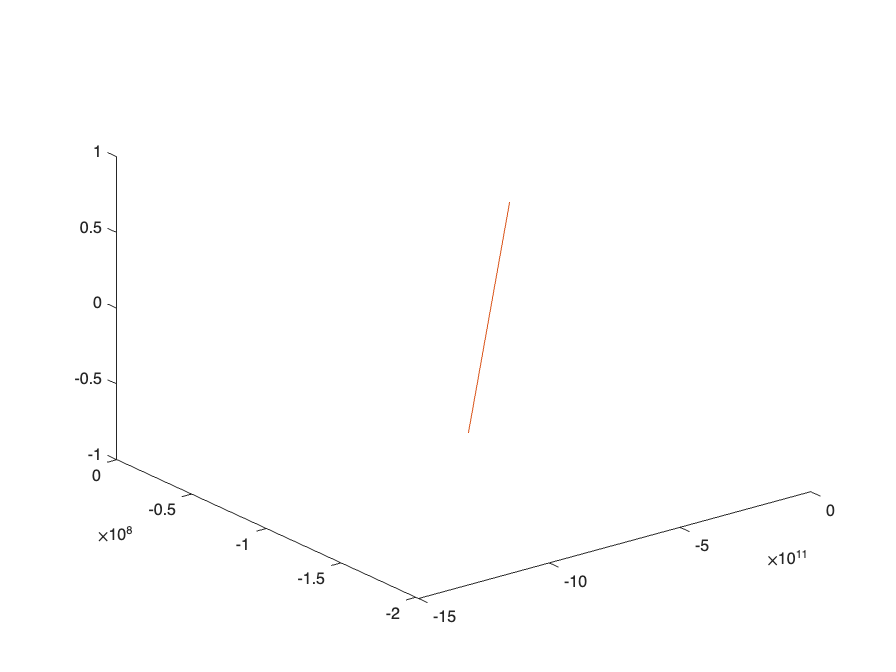

% Plot the path of orbit
plot3(x1(:, 1), x1(:, 2), x1(:, 3));
hold on
plot3(x2(:, 1), x2(:, 2), x2(:, 3));


% % Show the path of orbit along the line. See:
% % https://www.mathworks.com/help/matlab/creating_plots/trace-marker-along-line.html
% p1 = plot3(x1(1, 1),x1(1, 2),x1(1, 3),'o','MarkerFaceColor','red');
% p2 = plot3(x2(1, 1),x2(1, 2),x2(1, 3),'o','MarkerFaceColor','red');
% 
% for k = 2:length(t)
%     p1.XData = x1(k, 1);
%     p1.XData = x1(k, 2);
%     p1.XData = x1(k, 3);
% 
%     p2.XData = x2(k, 1);
%     p2.XData = x2(k, 2);
%     p2.XData = x2(k, 3);
% 
%     drawnow
% end

% % DEBUG: let's break the orbit into its xy, yz, xz planes
% % xy plane
hold off

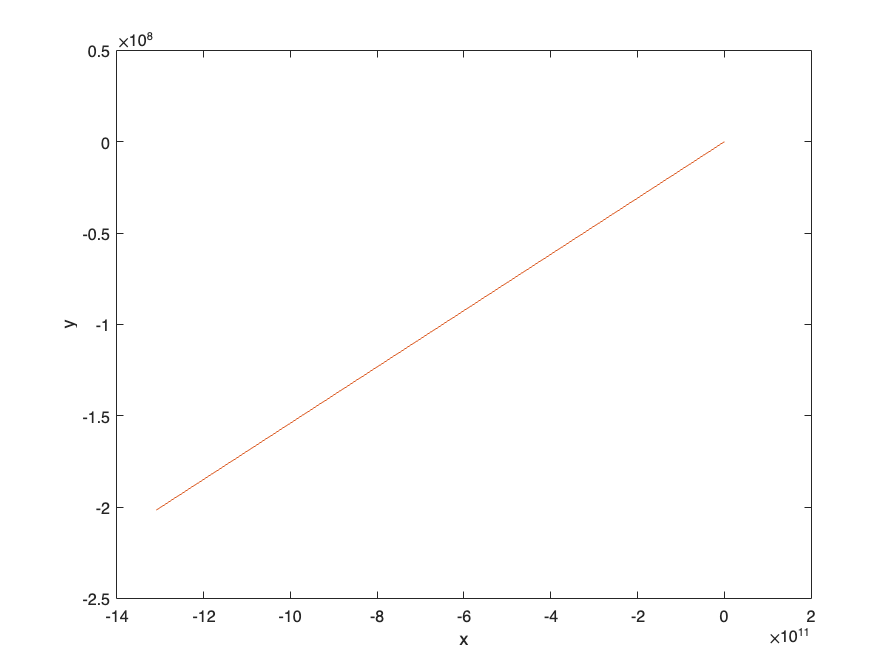

plot(x1(:, 1), x1(:, 2));
hold on
plot(x2(:, 1), x2(:, 2));
xlabel('x');
ylabel('y');

% yz plane
hold off

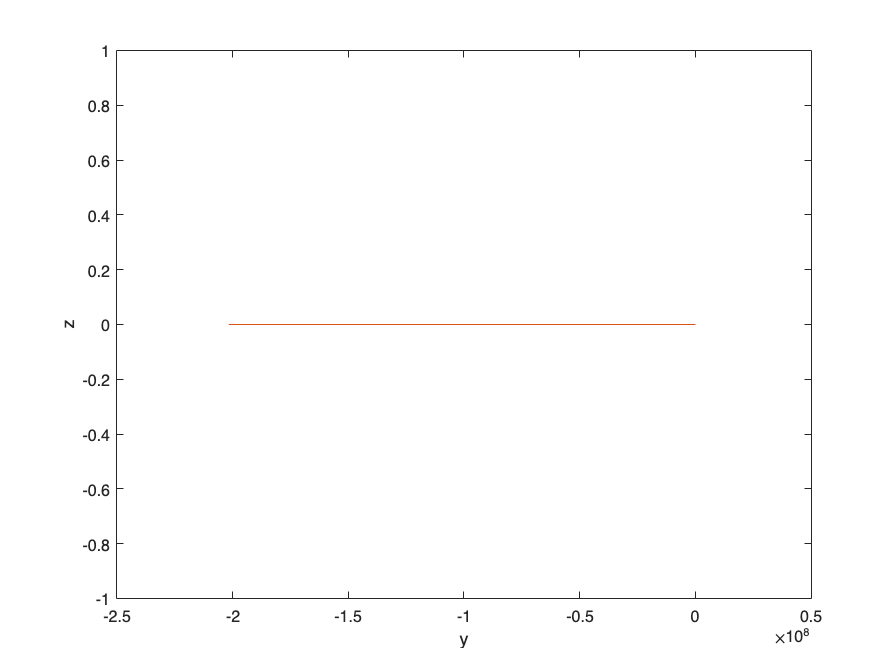

plot(x1(:, 2), x1(:, 3));
hold on
plot(x2(:, 2), x2(:, 3));
xlabel('y');
ylabel('z');

% xz plane
hold off

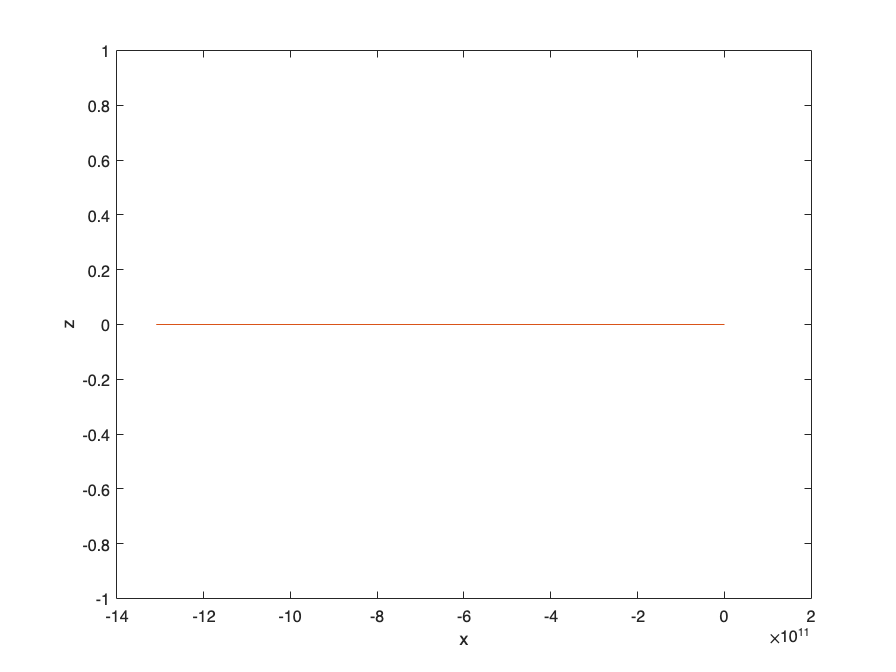

plot(x1(:,1), x1(:,3));
hold on
plot(x2(:,1), x2(:, 3));
xlabel('x');
ylabel('z');

% DEBUG: what do the velocity and acceleration graphs look like? Do they
% make sense?

% Acceleration xy plane
hold off

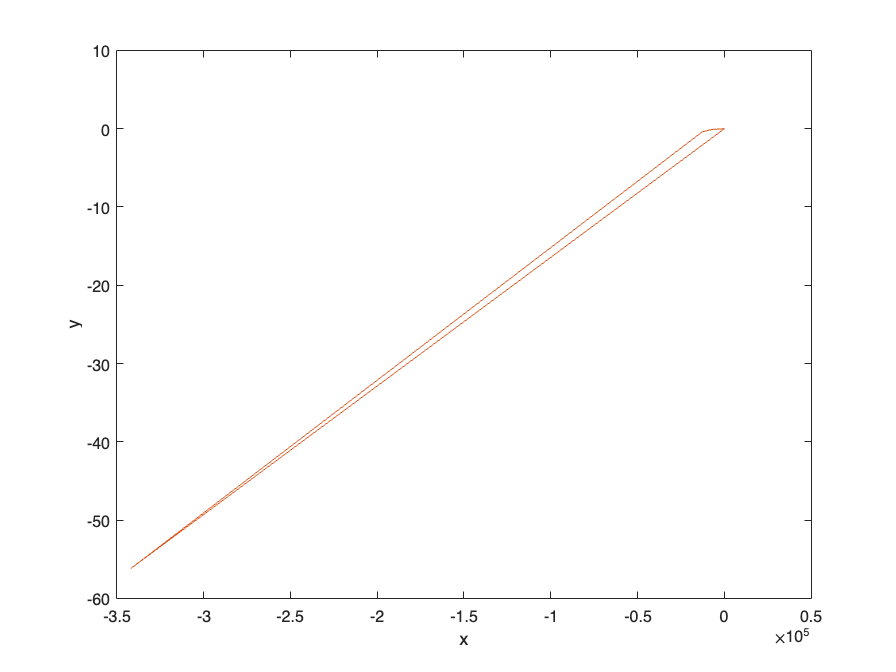

plot(x1(:, 7), x1(:, 8));
hold on
plot(x2(:, 7), x2(:, 8));
xlabel('x');
ylabel('y');

% Acceleration yz plane
hold off

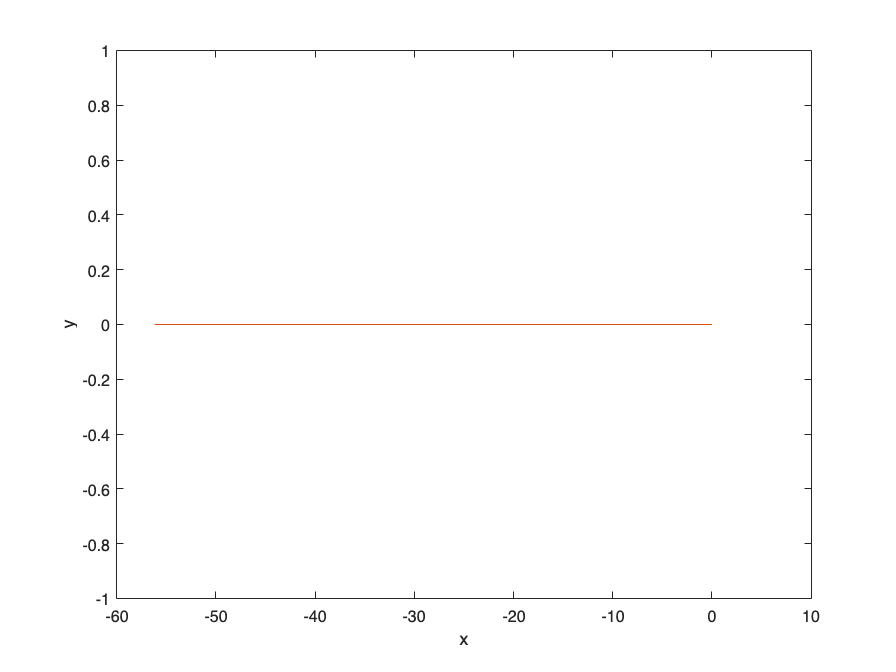

plot(x1(:, 8), x1(:, 9));
hold on
plot(x2(:, 8), x2(:, 9));
xlabel('x');
ylabel('y');

% Acceleration xz plane
hold off

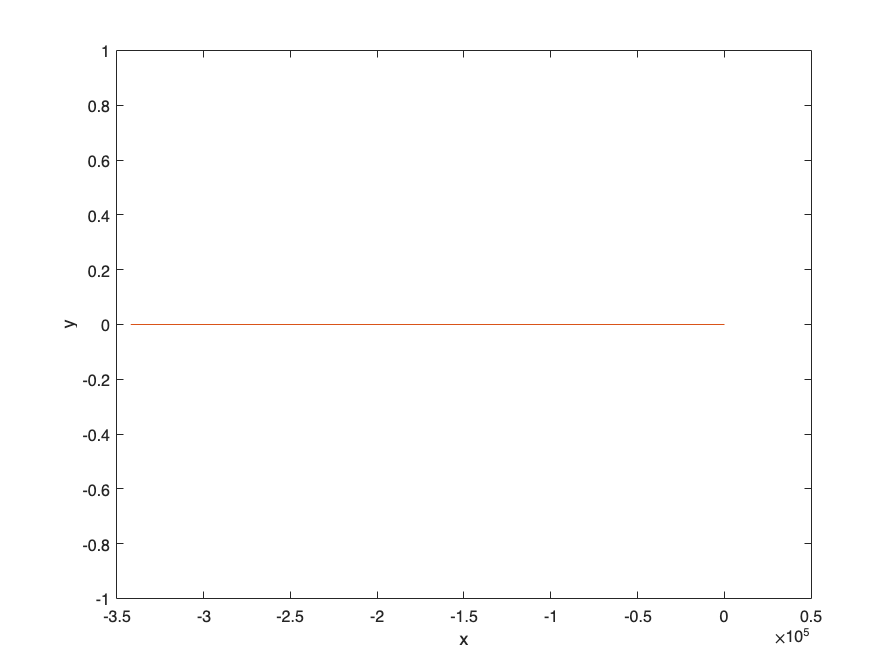

plot(x1(:, 7), x1(:, 9));
hold on
plot(x2(:, 7), x2(:, 9));
xlabel('x');
ylabel('y');

% DEBUG: Sanity check: compare the magnitude of acceleration to the
% magniture of distance; as the distance decreases, acceleration should
% increase.
hold off

plot(x1(:, 7), x1(:, 9));
hold on
plot(x2(:, 7), x2(:, 9));
xlabel('x');
ylabel('y');